# **Software Defined Radio (SDR) Project**

## Filter Design:

### **Problem Statement:**

The ideal filter is the one that has sharp transition between pass and stop bands; since it is practically inapplicable due to the infinitely long impulse response of the ideal filter, we try to compromise between the several filter characteristics in order to find the most optimized design. The trade –off between the filter design specifications is mainly between the filter complexity, represented in the filter order, against the favorable constraints we will seek to meet in our design which are: reducing the pass band attenuation, transition region, alongside with increasing the stop band attenuation as much as possible. 

In our design, we are mainly concerned about reconstructing each of the 8 uplinked signals, keeping in mind that there are only “20 kHz” between the end of the frequency span of one signal and the start of that of the next signal. Consequently, we are more likely to be disposed towards guaranteeing a relatively tiny “transition region” for the decided-on filter. Besides, as we are mainly trying to reconstruct the information bits that have been encoded at the transmitter side, it is considerably crucial to secure extremely small pass band ripples. On the other hand, the order of the filter (in other words, the number of filter coefficients) has to be kept relatively small in order to maintain less computations and unburdening complexity. 

### **Design Constraints:**

**The stop band attenuation:**

-Measuring the difference in magnitude of one of the generated signals, it has been found that that the difference between the signal magnitude at “90kHz” (the end of the signal’s frequency span) and the signal magnitude at “110kHZ” (which is supposed to be the start frequency of the next signal) is around -21 dB; Accordingly, the constraint of stop band attenuation is to be greater than (in the negative side) or equal 21dB (in the negative side). 

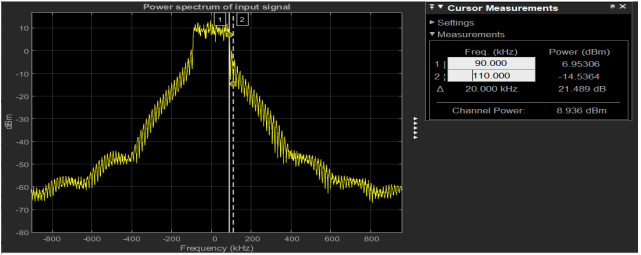

**The transition region:**

-Visualizing the transmitted signal (the frequency multiplexing of the 8 uplink generated signals), it has been found out that according to the standard of format 1 transmission, the bandwidth of each signal is “180” kHz with a span “200 kHz” representing the spacing between the center frequencies of every two consecutive signals, leaving only “20 kHz” as a guard band between the two signals. Therefore, the transition region of our design should range between 20 kHz and maximum of 30 kHz, so that at 20 kHz away from the signal, the attenuation value will be considerably small as not to distort our signal. 

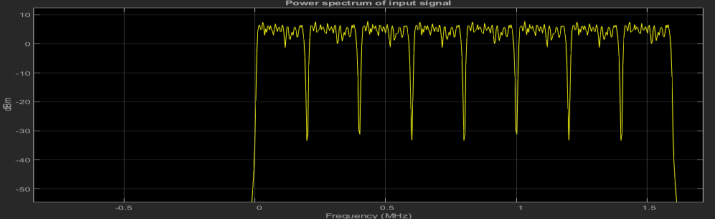

 '**Filter Complexity: (Filter order)**

The filter complexity is represented in the form of a dimensionless number counting the number of coefficients of the filter or the number of taps. The number of coefficients is proportional to the number of multiplications executed through applying the filter. Accordingly, increasing the number of filters will result in increasing the filter’s complexity and the number of computations. Therefore, it will be more preferable to decrease the filter order. According to the digital filtering problem we are dealing with, it will be quite satisfying to have a filter order of no more than 200.

**Pass band Ripples:**

The pass band ripples represent the distortion of the filter within the pass band, and the anticipated attenuation that will take place at the pass band of the signal. Given the digital filtering problem we are handling, it is considerably significant to guarantee the least distortion possible to our pass frequencies in order to be capable of reconstructing the input binary bits that have been generated at the transmitter side. Consequently, having a low value for the pass band ripples is desirable, and it will be more favorable to have a pass band ripples value ranging from 0.2 dB to 0.3 dB

### **Design process:**

**The filter prototypes:**

We have chosen 5 different designs in order to iterate and compare every one of the prototypes with the constraints and the requirements we have decided on for our optimal filter design. The following table shows the five designs input arguments given for every one of the five design methods.

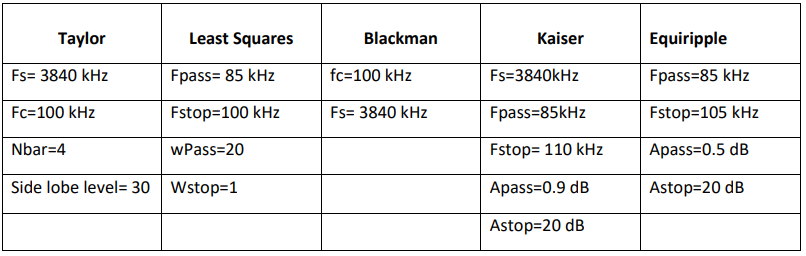

### **Qualitative analysis of the prototypes:**

**Taylor: (Window filter)**

This window type, accompanied by the input arguments stated above have managed to guarantee extremely small pass band ripples and high negative stop band attenuation. However, its transition region bandwidth was a fatal misleading factor that will surely result in eliminating this design from the nominees. 

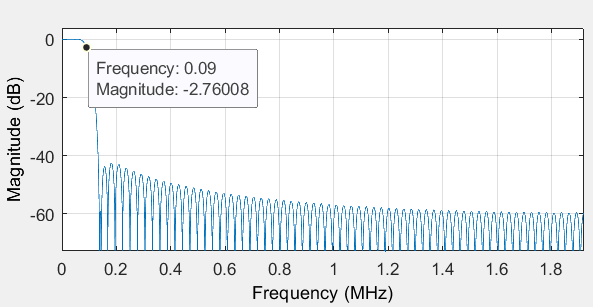

**Least Squares: **

This filter prototype was capable of performing relatively well at low orders through maintaining acceptable range of values when it comes to the pass band ripples. On the other hand, the filter’s stop band attenuation was quite distorting and it will drastically influence our signal. Besides, while visualizing the frequency response of the filer within the linear scale, it was plainly noticeable that its transition region bandwidth cannot be tolerated through our filtering process. Yet, this filter is still a favorable nominee. 

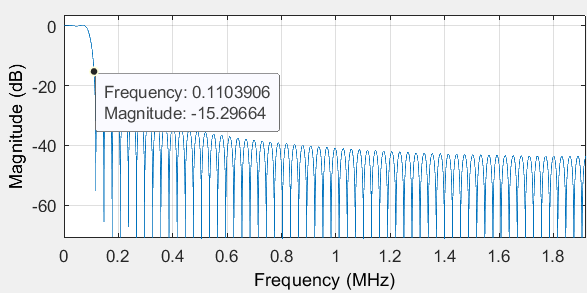

**Blackman: (Window filter)**

Despite achieving over satisfying values with respect to the pass band ripples and stop band attenuation, the Blackman window filter did not manage to sustain an acceptable transition region bandwidth; in addition, the complexity of the filter was not relatively small. 

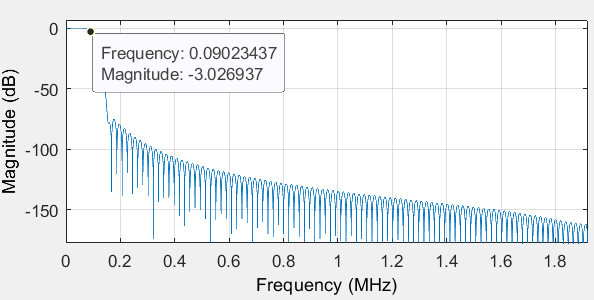

**Kaiser: (Window filter)**

As for this filter, it can be visualized through showing its response that it has managed to make the best trade – off so far. It has been noticed through visualization that this filter did not come out with any diverged parameter. Acceptable trade-off for 3 of the parameters: pass band ripples, stop band attenuation, and transition region bandwidth, accompanied by an order that is not counted as a bad compromise, have pushed this filter to be a strong candidate. 

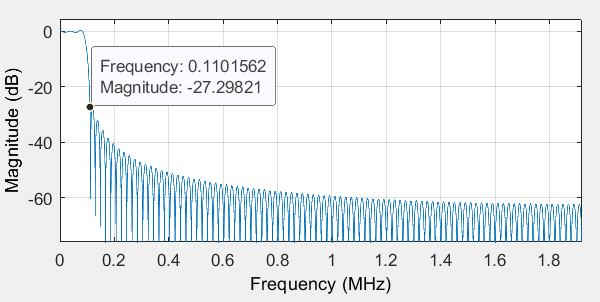

**Equiripple:**

Regarding the equiripple filter, it has managed to give a relatively good compromise between the filter constraints through having satisfying stop band attenuation and transition region bandwidth, alongside with relatively good value of pass band ripples. This filter also is to be taken into consideration with great concern.

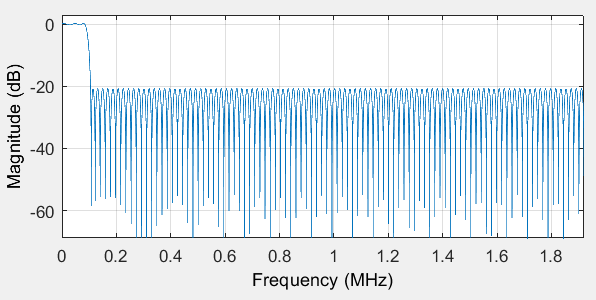

### **Quantitative Analysis:**

The next step includes calculating the values of the filter parameters represented in: Filter order, Pass band ripples, Stop band attenuation, and transition region bandwidth. The following table illustrates the output values of each of the five prototypes.

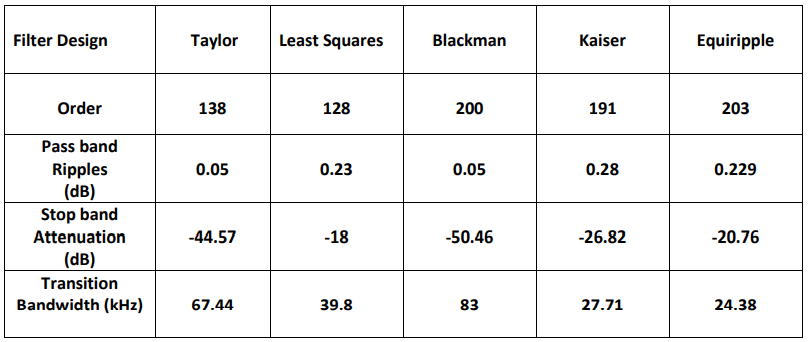

### **The evaluation criteria:**

The selection will be based upon the constraints and requirements we have stated. Each prototype will be given a score of compatibility to measure the convenience of each design. The score will be given out of 8 points; 2 for each constraint. Every prototype will be given a number of points for each constraint ranging from “-1” to “2” according to the level of resemblance compared to our designed constraint.  The design that will achieve the highest score of compatibility with our design constraints will be utilized in both the transmission and the reception processes. The following table shows the scoring range for each filter parameter. 

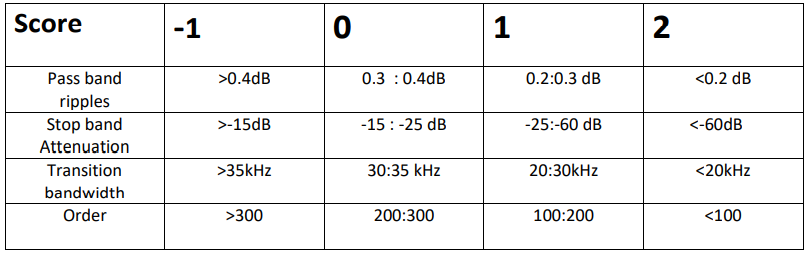

### **Implementation of the evaluation criteria:**

Scoring every design will be done using an iterative code which will give a certain score for each prototype based on the above criteria and choose the most convenient design according to our digital filtering problem. 

Constructing an array holding the specifications of the five proposed prototypes. The specifications are: pass band ripples(dB), stop band attenuation(dB), transition region band width (kHz), and filter order, respectively. The filter design process will include an iteration process on the specifications of the five designs and scoring each design based on the quantitative evaluation criteria attached. The prototype having the highest score will be implemented within the transmission and receiving stages. 


  % Concatenate each filter's specifications together in a single array
   Equiripple_specs= [0.229,-20.76,24.38,203];
   Taylor_specs= [0.05,-44.57,67.44,138];
   Leastsq_specs= [0.23,-18,39.8,128];
   Kaiser_specs= [0.28,-26.82,27.71,191];
   Blackman_specs= [0.05,-50.46,83,200];
   Specs= [Equiripple_specs Taylor_specs Leastsq_specs Kaiser_specs Blackman_specs]

Specs =     0.2290  -20.7600   24.3800  203.0000    0.0500  -44.5700   67.4400  138.0000    0.2300  -18.0000   39.8000  128.0000    0.2800  -26.8200   27.7100  191.0000    0.0500  -50.4600   83.0000  200.0000


Iterating on every filter's specifications in order to chose the filter with highest score according to the evaluation criteria

scores=zeros(1,5);
j=1; k=1;
   for i=1:length(Specs) 
        
       if mod((i-1),4)==0 && i>1
           j=j+1;
       end

% Scoring the filter's passband ripples value according to the evaluation criteria 
    if k==1
        if Specs(i)>0.4
        scores(j)=scores(j)-1;

        elseif Specs(i)>0.3 && Specs(i)<0.4
        scores(j)=scores(j);

        elseif Specs(i)>0.2 && Specs(i)<0.3
          scores(j)=scores(j)+1;

        else
        scores(j)=scores(j)+2;
        end

% Scoring the filter's stopband attenuation value for each filter design 

  elseif k==2

        if Specs(i)>-15
        scores(j)=scores(j)-1;

        elseif Specs(i)>-25 && Specs(i)<-15
        scores(j)=scores(j);

        elseif Specs(i)>-60 && Specs(i)<-25
          scores(j)=scores(j)+1;  

        else
        scores(j)=scores(j)+2;
        end

% Scoring the filter's transition region bandwidth value for each filter design 
    elseif k==3

        if Specs(i)>35
        scores(j)=scores(j)-1;

        elseif Specs(i)>30 && Specs(i)<35
        scores(j)=scores(j);

        elseif Specs(i)>20 && Specs(i)<30
          scores(j)=scores(j)+1;  

        else
        scores(j)=scores(j)+2;
        end

% Scoring the filter's order (number of coefficients) for each filter design 
    else
        if Specs(i)>300
        scores(j)=scores(j)-1;

        elseif Specs(i)>201 && Specs(i)<300
        scores(j)=scores(j);

        elseif Specs(i)>100 && Specs(i)<201
          scores(j)=scores(j)+1;  

        else
        scores(j)=scores(j)+2;
        end
    end
   if k==4
    k=0;
   end
   k=k+1;
   end


Importing the coefficients of the filter design that got the best score and displaying the optimal filter window type, alongside with its coefficients and frequency response. 

   %getting the index of the filter having the highest score
   [Mx,I] = max(scores);

   %Importing the filter coefficients of the optimal filter
   if I==1
      Filter_optimal= cell2mat(struct2cell(load('Equiripple.mat')));
      disp("Optimal Filter has been found to be Equiripple");

   elseif I==2
      Filter_optimal= cell2mat(struct2cell(load('Taylor.mat')));
      disp("Optimal Filter has been found to be Taylor");

   elseif I==3

      Filter_optimal= cell2mat(struct2cell(load('leastsq.mat')));
      disp("Optimal Filter has been found to be Least squares");

   elseif I==4
      Filter_optimal= cell2mat(struct2cell(load('Kaiser.mat')));
      disp("Optimal Filter has been found to be Kaiser");

   else 
      Filter_optimal= cell2mat(struct2cell(load('Blackman.mat')));
      disp("Optimal Filter has been found to be Blackman");
   end

Optimal Filter has been found to be Kaiser


### The evaluation process output:

 After the code execution of the evaluation process, the highest score was achieved by the Kaiser  Window Filter. The filter was utilized in both the transmission and the receiving of the NB-iot signal, and  expectedly, it performed exceedingly well on the signal and managed, to a great extent to deal with our  digital filtering.

   
   %Visulaizing the filter coefficients and the frequency response of the
   %filter
   disp(Filter_optimal);

  Columns 1 through 7

    0.0009    0.0012    0.0015    0.0018    0.0020    0.0022    0.0023

  Columns 8 through 14

    0.0024    0.0024    0.0023    0.0022    0.0020    0.0018    0.0015

  Columns 15 through 21

    0.0012    0.0008    0.0003   -0.0001   -0.0006   -0.0011   -0.0015

  Columns 22 through 28

   -0.0020   -0.0024   -0.0028   -0.0031   -0.0033   -0.0035   -0.0036

  Columns 29 through 35

   -0.0036   -0.0035   -0.0033   -0.0030   -0.0026   -0.0021   -0.0016

  Columns 36 through 42

   -0.0010   -0.0003    0.0004    0.0011    0.0019    0.0026    0.0033

  Columns 43 through 49

    0.0039    0.0045    0.0050    0.0053    0.0056    0.0057    0.0057

  Columns 50 through 56

    0.0055    0.0051    0.0046    0.0040    0.0032    0.0023    0.0013

  Columns 57 through 63

    0.0001   -0.0011   -0.0023   -0.0036   -0.0048   -0.0060   -0.0071

  Columns 64 through 70

   -0.0081   -0.0090   -0.0097   -0.0101   -0.0104   -0.0104   -0.0101

  Columns 71 through 77

   -0.00

   disp("The filter's frequency response");

The filter's frequency response


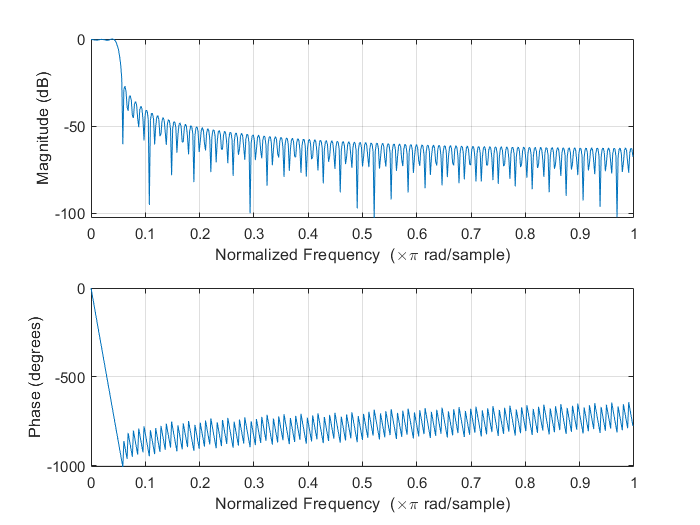

   freqz(Filter_optimal,1);

## **The Transmitter Side: (UL NB-IoT devices)  **

% defining The IF of the first signal and the subspacing 
% between the carriers
subspacing= '15kHz';
IF_1=1e05;
trans_signal=zeros(30720,1);

for i=1:8
%generating each of the 8 uplink complex baseband waveforms
     [wave,Fs]=generate_NBiot(subspacing);
if i==4
generated = dsp.SpectrumAnalyzer('SampleRate',Fs,'Title',' The uplink generated waveform signal');
  generated(wave);
end

Upsampling each of the 8 signals and applying a low pass FIR filter to capture the frequency span of the signal. The FIR filter applied is the one we settled on after our filter design process. 

   
%Upsampling the signal by a factor of 2 in order to perform DUC
%new_Fs=3.84MHz
    wave_up=upsample(wave,2);

%filtering the signal in order to remove any noise lying outside the
%bandwidth of the signal using a window FIR low pass filter
    wave_filtered=filter(Filter_optimal,1,wave_up);


Digital Up conversion of every signal to its intermediate frequency. The output of this stage is the composite IF signal that will be received at the base station. 

%Calculating the Intermediate frequency of each waveform and digitally upconverting
%the signal into this IF
new_Fs=Fs*2;
IF=IF_1+(2*IF_1*(i-1));
N=0:length(wave_filtered)-1;
DUC =exp(-j*2*pi*N*IF*(1/new_Fs));
 wave_sh = DUC'.*wave_filtered;

 % Frequency multiplexing of the 8 signals to be trasmitted
 trans_signal=trans_signal+wave_sh;
end

Unrecognized function or variable 'lteNBResourceGrid'.

Error in generate_NBiot (line 68)
emptySlotGrid = lteNBResourceGrid(ue);


% Visualizing the frequency domain of the transmitted signal 
  inputSpectrum = dsp.SpectrumAnalyzer('SampleRate',Fs*2,'Title',' The magnitude spectrum of the composite IF signal');
  inputSpectrum(trans_signal);

## **Receiving at the base station:**

The received composite IF signal goes through several procedures at the base station in order to reconstruct the uplink generated waveform at the transmitter side. The procedures are digital downconversion, followed by FIR filtering using a low pass filter

done=zeros(length(trans_signal)/2,8);
wave_shtotal=zeros(length(trans_signal),8);
wave_ftotal=zeros(length(trans_signal),8);

 for i=1:8
% Performing DDC on every signal to shift its center frequency to zero
IF=IF_1+(2*IF_1*(i-1));
N=1:length(trans_signal);
DUC =exp(1i*2*pi*N*IF*(1/new_Fs));
wave_shtotal(:,i) = DUC'.*trans_signal;


%filtering the signal in order to remove any noise lying outside the
%bandwidth of the signal using a window FIR low pass filter

    wave_ftotal(:,i)=filter(Filter_optimal,1,wave_shtotal(:,i));

 % Downsampling the signal by a factor of 2 
    done(:,i)=downsample(wave_ftotal(:,i),2);
 end

  

The 3 plots of one of the received NB-IoT waveforms (specifically of 4th order) 

First plot: after the digital down conversion process.

Second plot: after passing the signal through FIR low pass filter.

Thrid plot: after downsampling the signal by a factor of 2 to obtain the frequency of the uplink waveform generation.

disp("The Following 3 plots demonstrating the 4th received NB-IoT " + ...
    "waveform in different stages at the base station \n");

outputspectrum = dsp.SpectrumAnalyzer('SampleRate',Fs*2, 'Title','After Digital Down conversion stage');
outputspectrum(wave_shtotal(:,4));



outputspectrum_2 = dsp.SpectrumAnalyzer('SampleRate',Fs*2,'Title','After FIR Filtering stage');
outputspectrum_2(wave_ftotal(:,4));


outputspectrum_3 = dsp.SpectrumAnalyzer('SampleRate',Fs,'Title','After the downsampling stage');
outputspectrum_3(done(:,4));

## Block Diagrams

### Block Diagram of the 8 IoT devices transmitters:

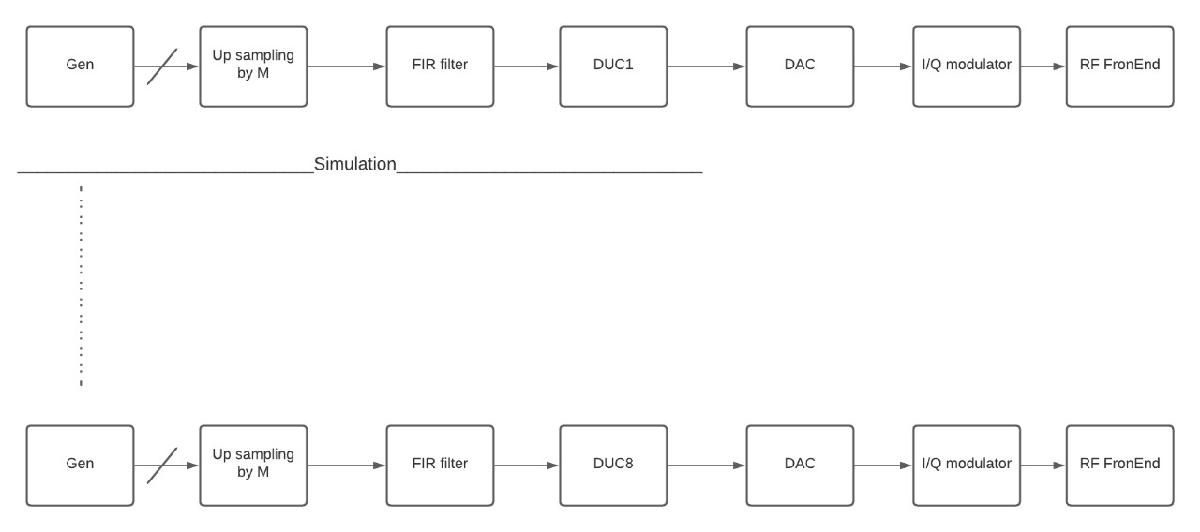

### Block Diagram of the base station receiver:

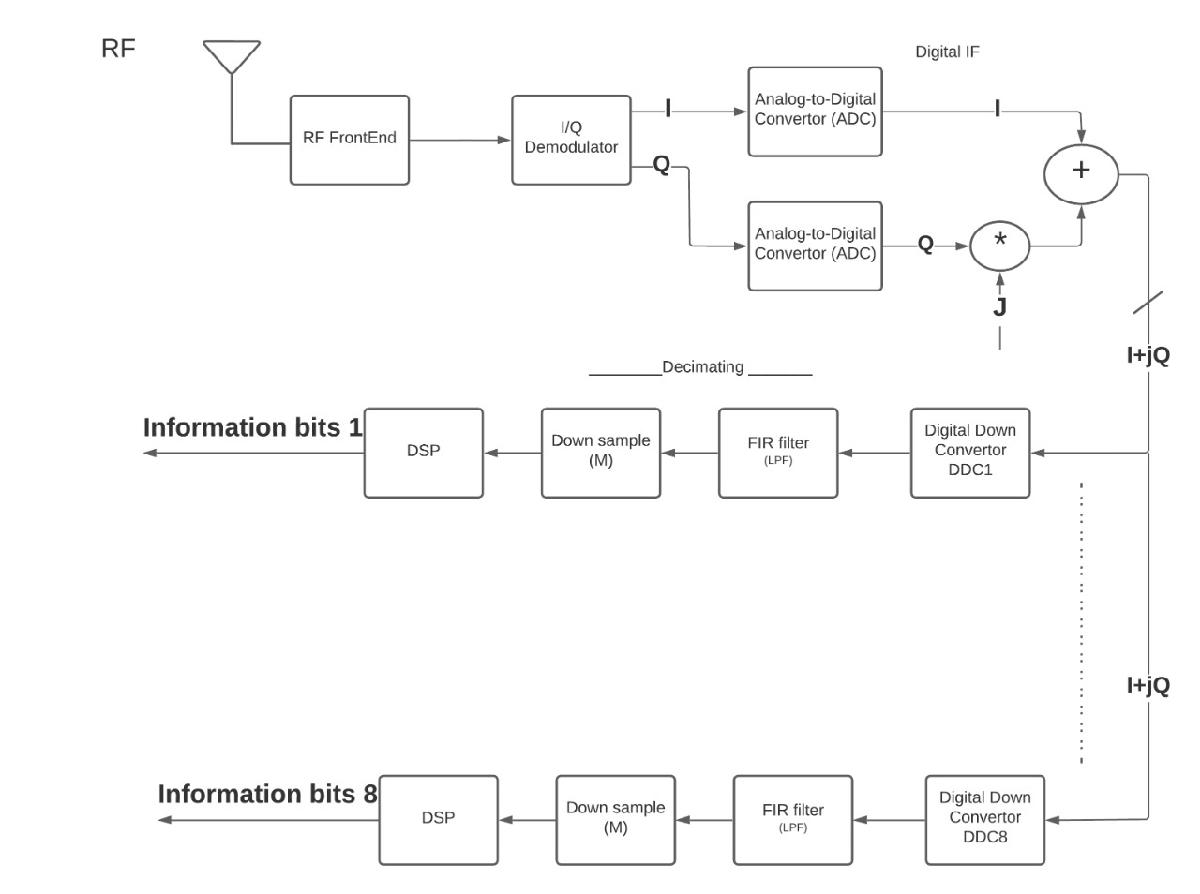

##  Discussion of NB-IoT application

Technologies with simpler waveform — like NB-IoT — will consume less power. A 200 kHz NB-IoT frontend and digitizer offers reduced complexity of analog-to-digital (A/D) and digital-to-analog (D/A) conversion, buffering, and channel estimation. Power savings = cost savings. Plus, NB-IoT chips are simpler to create and thus come cheaper.

Smart Hospitals:

A growing trend looks to change the experience of the healthcare environment for patients, providing new means of communication and entertainment at their reach, particularly aimed at patients with restricted mobility (acute, recovering, and long-term patients). These proposals integrate connectivity and a higher control over the environment, while including informative resources concerning different conditions. Even when not including control over the bed itself, these “Interactive Patient-Care Systems” may integrate a touchscreen through adjustable stands.

social: it allows us to control all  Embedded monitoring, autonomous responses and accessibility-enabled systems can take full advantage of the potential of these devices

economic: It's cost saver as the technologies implemented into smart medical beds may, result in derived, low-cost upgrades to other devices, like manually-operated beds, which less-developed regions can benefit from.

scientific impact: allow researchers to track more needed variable along time and reach that data immediatly(all data autherties are reserved).

**references:**

https://bmcmedinformdecismak.biomedcentral.com/articles/10.1186/s12911-018-0643-5